clear
clc

loadSim

Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Elapsed time is 0.058483 seconds.
Data loaded


y = D06_05_h05_Ef_Ac05H0108_R01.data(:,2:3);
u = D06_05_h05_Ef_Ac05H0108_R01.data(:,5);
z = iddata(y, u, 0.05, 'Name', 'Pendulum');
z.OutputName = {'Pendulum position','Flywheel angular velocity'};
z.OutputUnit = {'rad','rad/s'};
z.InputName = {'Control Signal'};
z.Tstart = 0;
z.TimeUnit = 's';

FileName      = 'flywheel_extended';        % File describing the model structure.
Order         = [2 1 3];             % Model orders [ny nu nx].
Parameters    = [9.81; 0.209; 0.18; 0.492; 0.05; 2.3e-4; 0.029; 0.027; 0.025; 0.5; 1.32e-6];   % Initial parameters. %g,Mf,lf,mp,lp,Jf,Jm,c_u,c_v
InitialStates = [0; 0; 0];              % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum position','Flywheel angular velocity'};
nlgr.OutputUnit = {'rad','rad/s'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum position' 'Pendulum velocity' 'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'Gravity constant' 'Flywheel mass' 'flywheel length' 'pendulum mass' 'pendulum cog length' 'flywheel inertia' ...
    'pendulum inertia' 'motor torque constant' 'back emf constant' 'motor resistance' 'dynamic friction torque'});
nlgr = setpar(nlgr, 'Unit', {'m/s^2' 'kg' 'm' 'kg' 'm' 'inertia' 'inertia' 'idk' 'idk' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0)});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {20 2 0.3 3 0.2 inf inf 2 1 inf 1e-4});   % All parameters > 0.


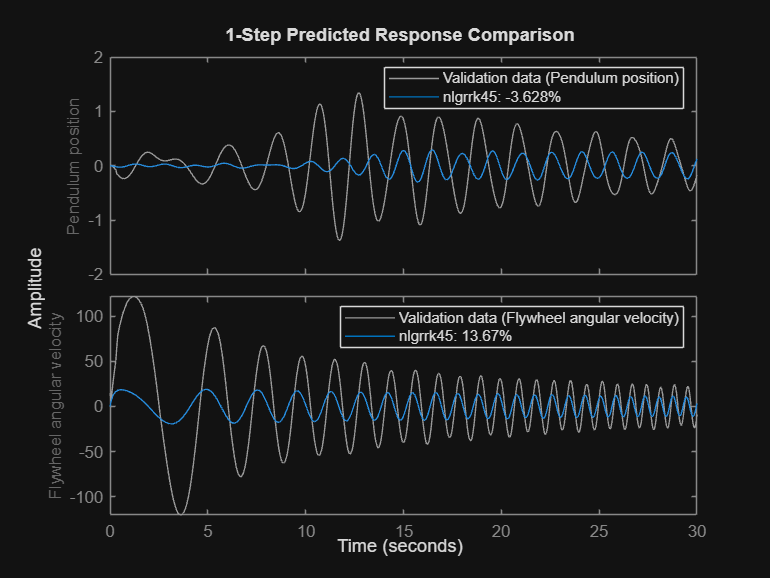

nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {true false false false false false false false false false false});

We finally use the Runge-Kutta 45 solver (ode45).

opt = nlgreyestOptions('Display', 'on');
opt.OutputWeight = [10,0;0,1];
nlgrrk45 = nlgreyest(z, nlgrrk45, opt)   % Perform parameter estimation.

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.5605;92.43]%                                        
FPE: 3.587, MSE: 12.59                                                          

Model Properties


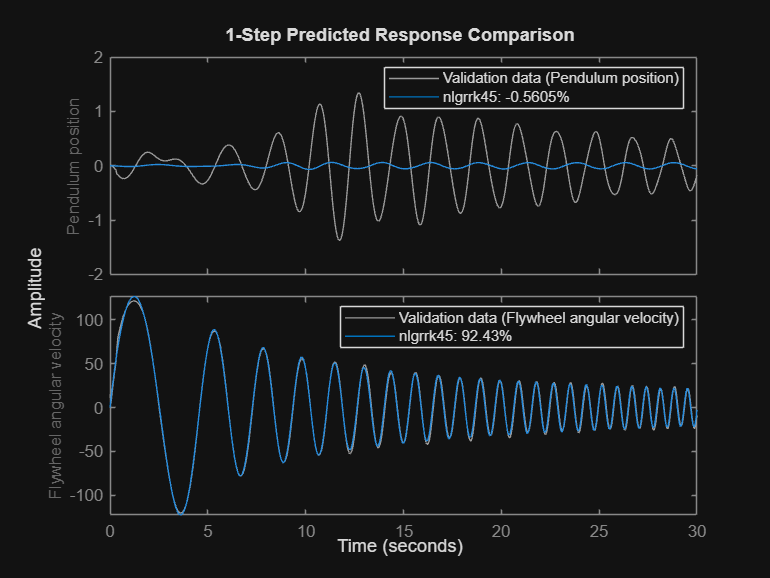

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

fpe(nlgrrk45);

    3.5873



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.06628;92.42]%                                       
FPE: 3.557, MSE: 12.6                                                           

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [63.43;57.56]%                                          
FPE: 38.55, MSE: 398.1                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [63.93;56.61]%                                          
FPE: 40.02, MSE: 416.1                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [57.14;90.14]%                                          
FPE: 1.082, MSE: 20.9                                                           

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


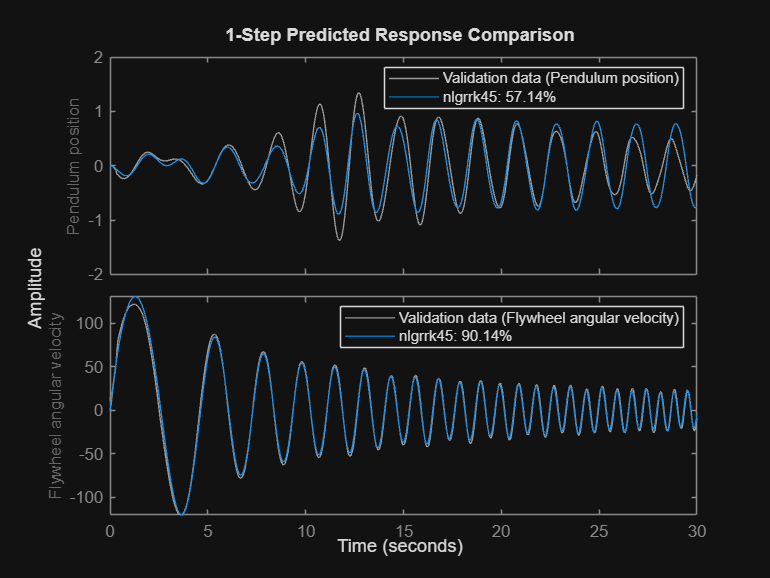

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [57.18;90]%                                             
FPE: 1.112, MSE: 21.54                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [62.91;59.81]%                                          
FPE: 33.91, MSE: 357                                                            

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [62.91;59.81]%                                          
FPE: 33.91, MSE: 357                                                            

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [56.4;91.38]%                                           
FPE: 0.86, MSE: 16.02                                                           

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


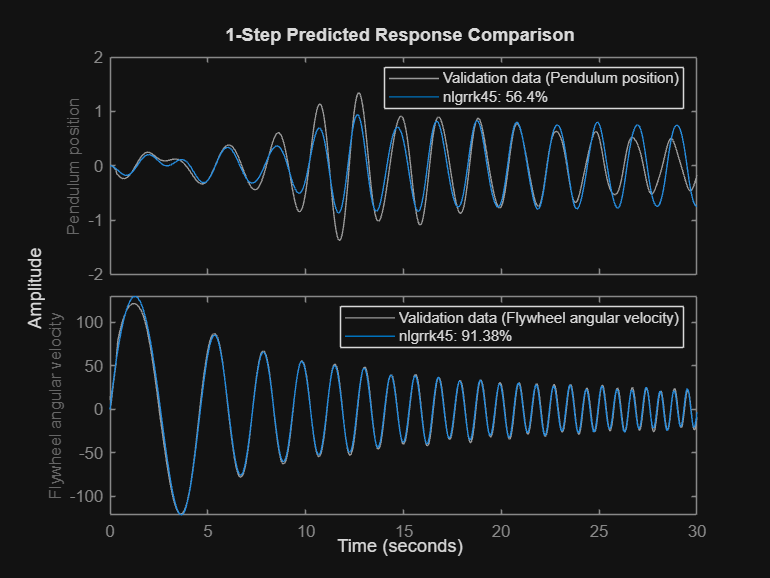

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [57.17;90.09]%                                          
FPE: 1.092, MSE: 21.13                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [63.9;56.72]%                                           
FPE: 39.84, MSE: 414.1                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [63.9;56.7]%                                            
FPE: 39.87, MSE: 414.4                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [57.16;90.1]%                                           
FPE: 1.09, MSE: 21.08                                                           

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


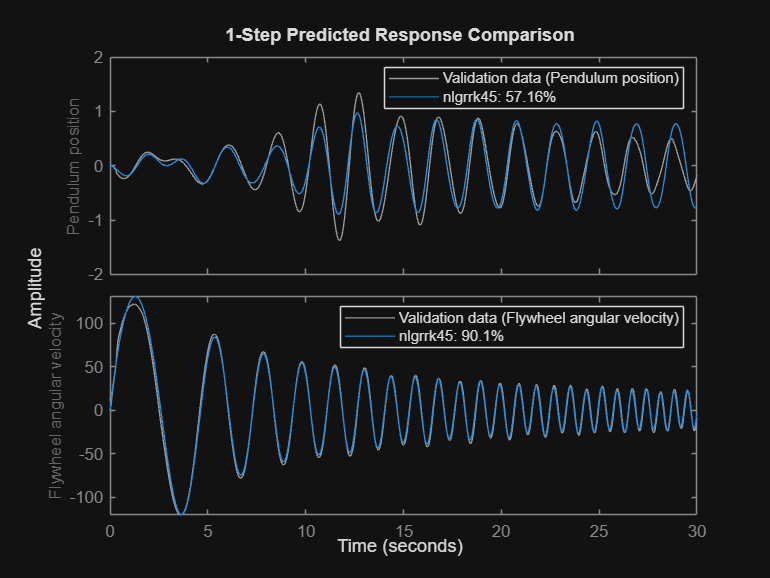

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [57.17;90.09]%                                          
FPE: 1.093, MSE: 21.14                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [63.91;56.66]%                                          
FPE: 39.93, MSE: 415.2                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [63.91;56.66]%                                          
FPE: 39.93, MSE: 415.2                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [57.15;90.19]%                                          
FPE: 1.073, MSE: 20.73                                                          

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


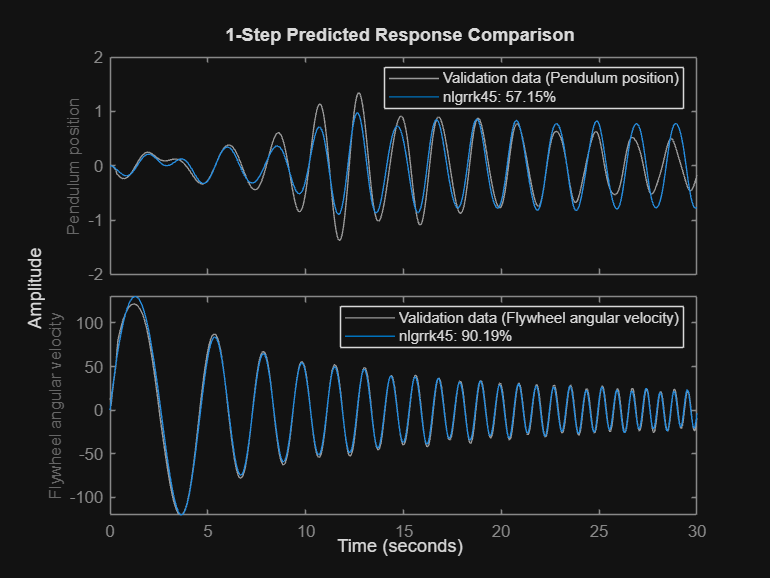

y = D06_05_h05_Ef_As05H05_R01.data(:,2:3);
u = D06_05_h05_Ef_As05H05_R01.data(:,5);
z2 = iddata(y, u, 0.05, 'Name', 'Pendulum');
z2.OutputName = {'Pendulum position','Flywheel angular velocity'};
z2.OutputUnit = {'rad','rad/s'};
z2.InputName = {'Control Signal'};
z2.Tstart = 0;
z2.TimeUnit = 's';


for i = 1:4 
    opt.OutputWeight = [10000,0;0,1];
    nlgrrk45 = nlgreyest(z,nlgrrk45, opt)
    nlgrrk45 = pem(z2,nlgrrk45, opt)
    nlgrrk45 = nlgreyest(z2,nlgrrk45, opt)
    nlgrrk45 = pem(z,nlgrrk45, opt)
    
    nlgrrk45.Parameters
    figure(i),clf;
        compare(z, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end